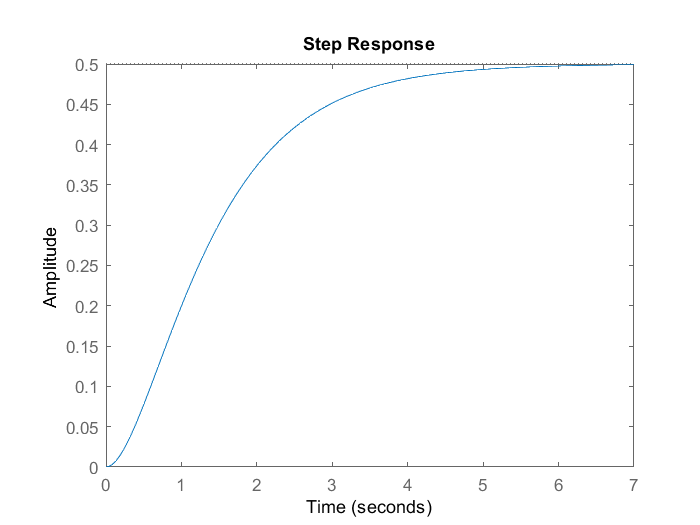

%  Step response of Transfer function 1/((s+1)(s+2))
num = 1;
den = [1 3 2];
g = tf(num,den);
figure(1)
step(g);

stepinfo(g)

ans = struct with fields:
        RiseTime: 2.5901
    SettlingTime: 4.6002
     SettlingMin: 0.4511
     SettlingMax: 0.4996
       Overshoot: 0
      Undershoot: 0
            Peak: 0.4996
        PeakTime: 7.7827


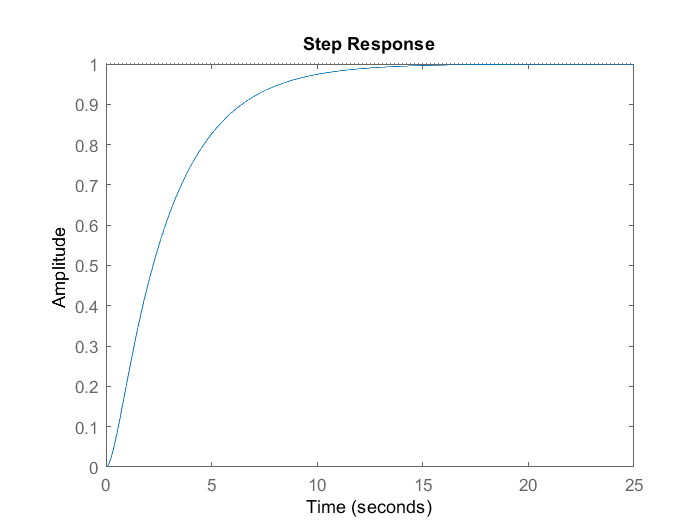

%% Step response of g with positive(1) feedback
t = feedback(g,1,1);
figure(2)
step(t);

stepinfo(t)

ans = struct with fields:
        RiseTime: 5.8584
    SettlingTime: 10.6547
     SettlingMin: 0.9012
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 25.9983


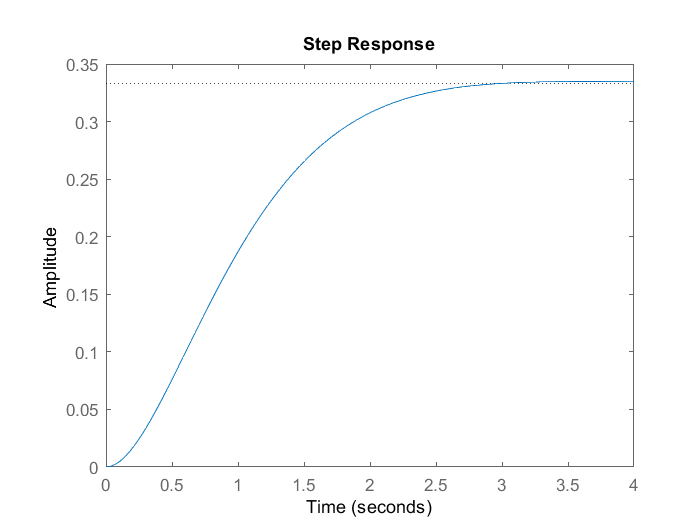

%% Step response of g with negative(1) feedback
t1 = feedback(g,1);
figure(3)
step(t1);

stepinfo(t1)

ans = struct with fields:
        RiseTime: 1.5787
    SettlingTime: 2.5089
     SettlingMin: 0.3017
     SettlingMax: 0.3348
       Overshoot: 0.4333
      Undershoot: 0
            Peak: 0.3348
        PeakTime: 3.6227


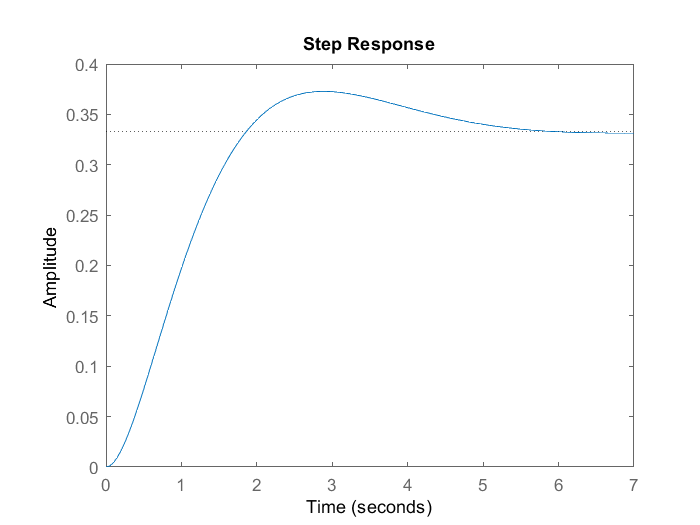

%% step response of g with s+1 pole in -ve feedback path
h1 = tf(1,[1 1]);
t2 = feedback(g,h1);
figure(4)
step(t2);

stepinfo(t2)

ans = struct with fields:
        RiseTime: 1.2722
    SettlingTime: 5.0078
     SettlingMin: 0.3047
     SettlingMax: 0.3728
       Overshoot: 11.8450
      Undershoot: 0
            Peak: 0.3728
        PeakTime: 2.8764


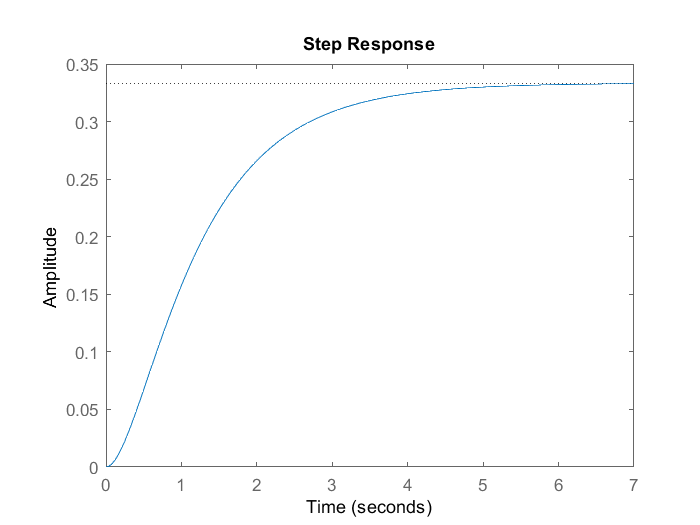

%% step response of g with s+1 zero in -ve feedback path
h2 = tf([1 1],1);
t3 = feedback(g,h2);
figure(5)
step(t3);

stepinfo(t3)

ans = struct with fields:
        RiseTime: 2.3911
    SettlingTime: 4.3175
     SettlingMin: 0.3008
     SettlingMax: 0.3332
       Overshoot: 0
      Undershoot: 0
            Peak: 0.3332
        PeakTime: 7.9516


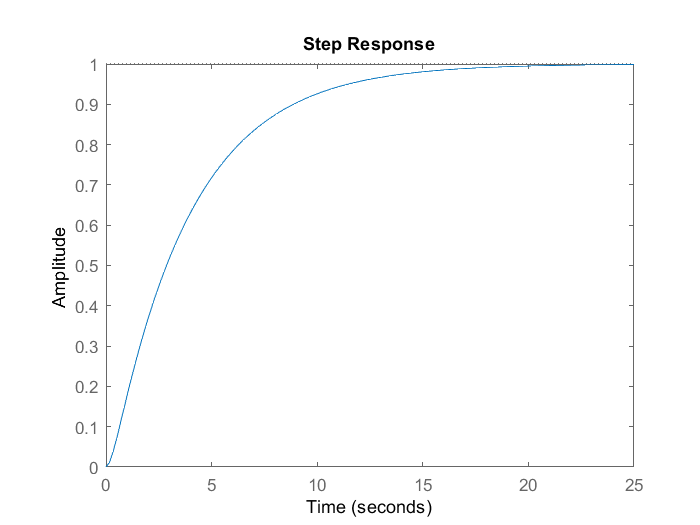

%% step response of g with s-1 zero in -ve feedback path
h3 = tf([1 -1],1);
t4 = feedback(g,h3);
figure(6)
step(t4);

stepinfo(t4)

ans = struct with fields:
        RiseTime: 8.2308
    SettlingTime: 14.8789
     SettlingMin: 0.9017
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 27.3269
